Roots

p1 = [3 -2 -4];

polyval(p1, 0)

ans = -4

r1 = roots(p1)

r1 =     1.5352
   -0.8685



p2 = [1 0 0 0 -1];
r2 = roots(p2)

r2 =   -1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
   1.0000 + 0.0000i



polyval(p2,-1)

ans = 0


3*poly(r1)

ans =     3.0000   -2.0000   -4.0000


poly(r2)

ans =     1.0000    0.0000   -0.0000    0.0000   -1.0000



real(r2)

ans =    -1.0000
    0.0000
    0.0000
    1.0000


imag(r2)

ans =          0
    1.0000
   -1.0000
         0


fzero

%doc fzero

fun = @sin;
x0 = 1

x0 = 1

x = fzero(fun, x0)

x = 1.5485e-24


x0 = -2

x0 = -2

x = fzero(fun, x0)

x = -3.1416

poly([-5, 1, 5])

ans =      1    -1   -25    25


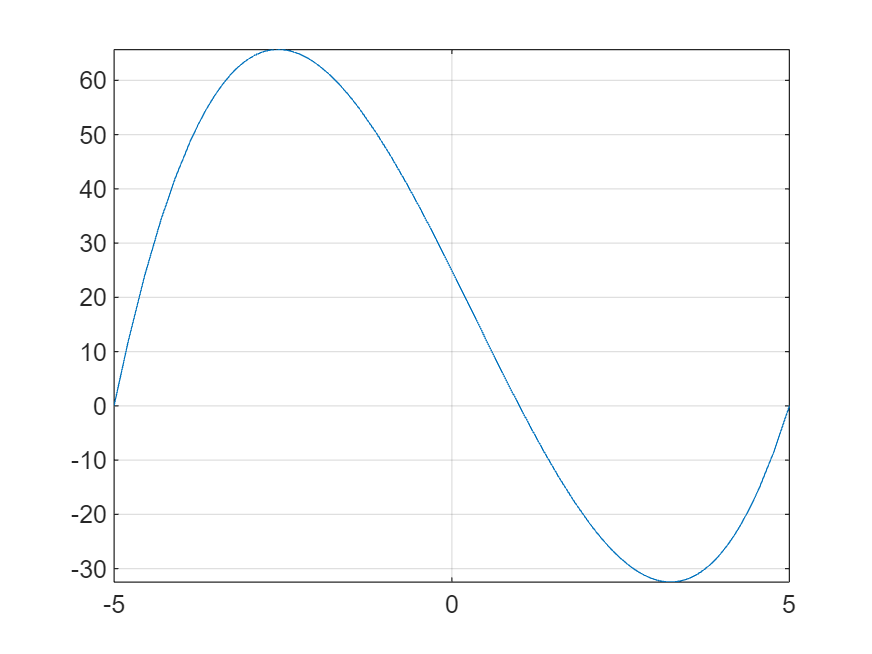

fun = @(x) x.^3 - x.^2 - 25.*x + 25;
fplot(fun)
grid on


x = fzero(fun, -3)

x = -5

x = fzero(fun, 3)

x = 1.0000

x = fzero(fun, 6)

x = 5


x = fzero(fun, [0 2])

x = 1.0000

x = fzero(fun, [-6 0])

x = -5

%x = fzero(fun, [-4 0])

fun = @(x) 1./x

fun = function_handle with value:
    @(x)1./x

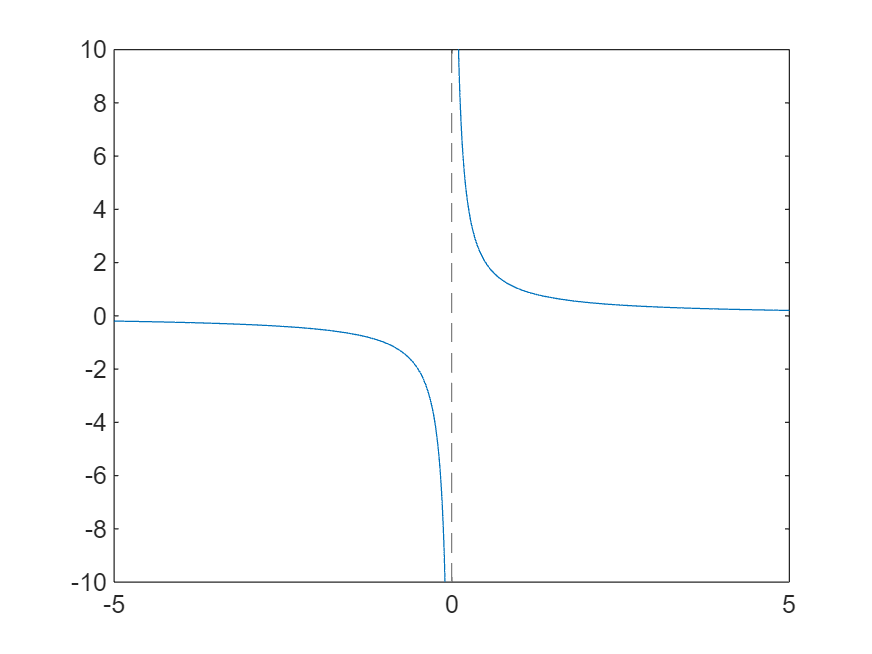

fplot(fun)

fzero(fun, [-1 1])

ans = -8.8818e-16

clear
c = 1:0.1:100

c =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


size(c)

ans =      1   991


A(size(c)) = 0

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


clear

myfun = @(x, c) cos(c.*x)

myfun = function_handle with value:
    @(x,c)cos(c.*x)


c = 1:0.1:2

c =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


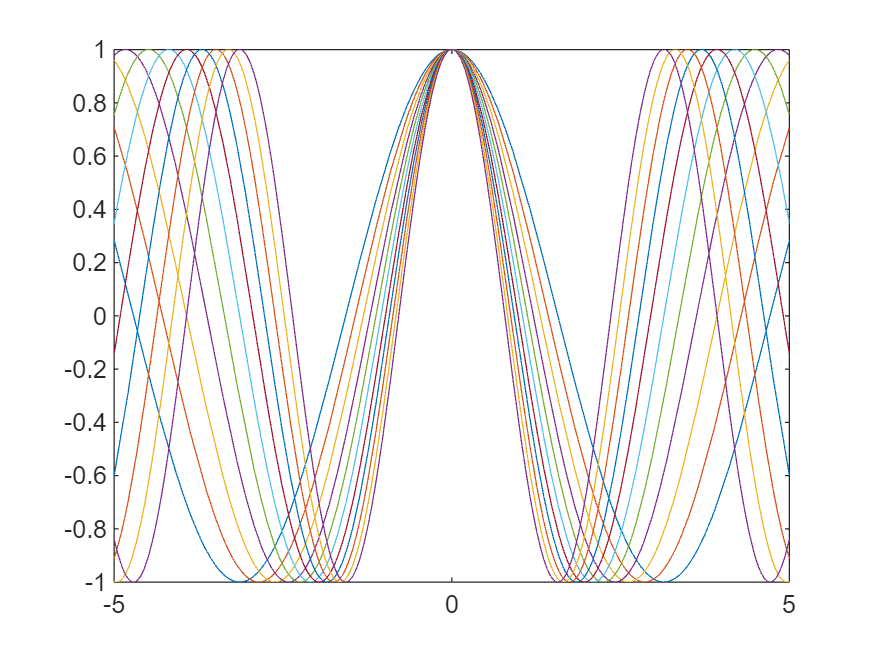

X(size(c)) = 0;

for i = 1:size(c,2)
    fun = @(x) myfun(x, c(i));
    X(i) = fzero(fun, 1);
    fplot(fun)
    hold on
end
hold off

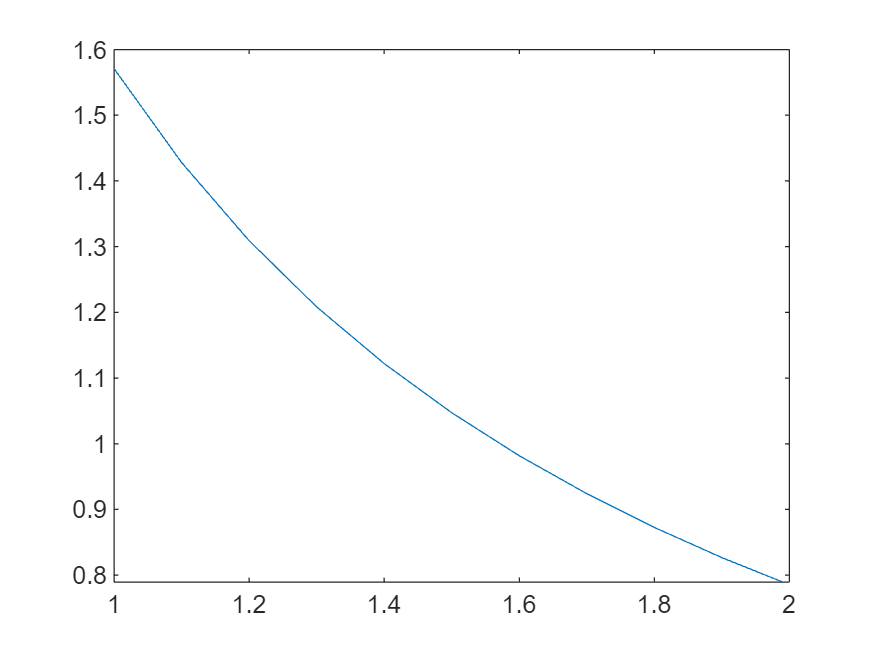

plot(c,X)

clear

myfun = @(x, c) cos(c.*x)

myfun = function_handle with value:
    @(x,c)cos(c.*x)


c = 1:0.1:10;

c =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


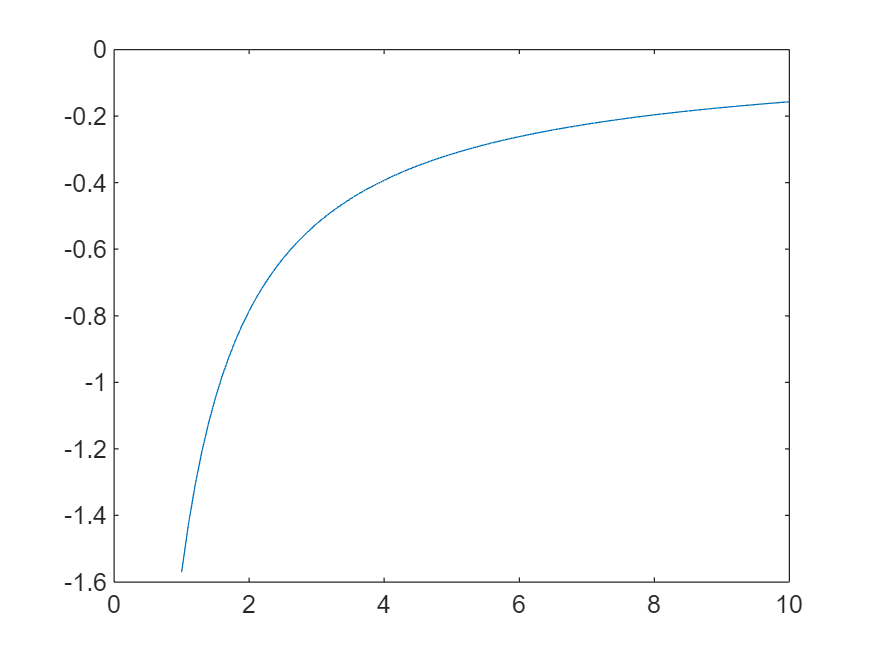

X(size(c)) = 0;

for i = 1:size(c,2)
    fun = @(x) myfun(x, c(i));
    X(i) = fzero(fun, 0.0001);
end
plot(c,X)

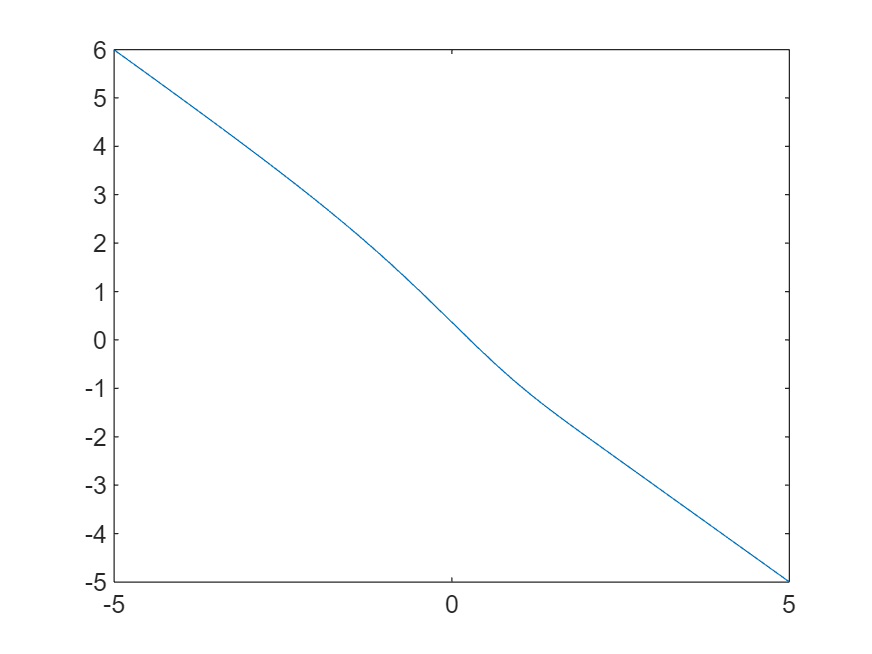

%doc fzero

fun = @(x) exp(-exp(x))-x;
fplot(fun)


x0 = [0 1]

x0 =      0     1


option = optimset('Display','iter');

x = fzero(fun,x0,option)

 
 Func-count    x          f(x)             Procedure
    2               0      0.367879        initial
    3        0.282573    -0.0171788        interpolation
    4        0.269967  -0.000125013        interpolation
    5        0.269874   2.28404e-08        interpolation
    6        0.269874  -8.53762e-14        interpolation
    7        0.269874             0        interpolation
 
Zero found in the interval [0, 1]


x = 0.2699

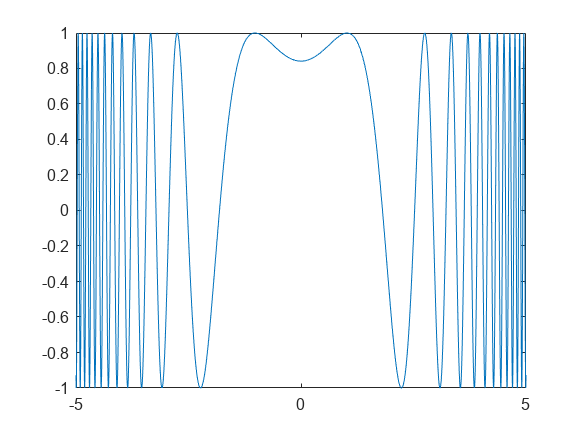

clc
clear
close all
fun = @(x) sin(cosh(x));
fplot(fun)


x0 = 10

x0 = 10

 
Search for an interval around 10 containing a sign change:
 Func-count    a          f(a)             b          f(b)        Procedure
    1              10     -0.928712            10     -0.928712   initial interval
    3         9.71716    -0.0933253       10.2828     -0.954944   search
    5             9.6       -0.3447          10.4      -0.65692   search
    7         9.43431     -0.279043       10.5657      0.551809   search
 
Search for a zero in the interval [9.43431, 10.5657]:
 Func-count    x          f(x)             Procedure
    7         9.43431     -0.279043        initial
    8         10.5657      0.551809        interpolation
    9         10.2971      0.987868        interpolation
   10         9.81429     -0.992134        bisection
   11         9.93493      0.665235        interpolation
   12         9.93493      0.665235        interpolation
   13         9.91558      -0.48862        interpolation
   14         9.91558      -0.48862        interpolation
   15 

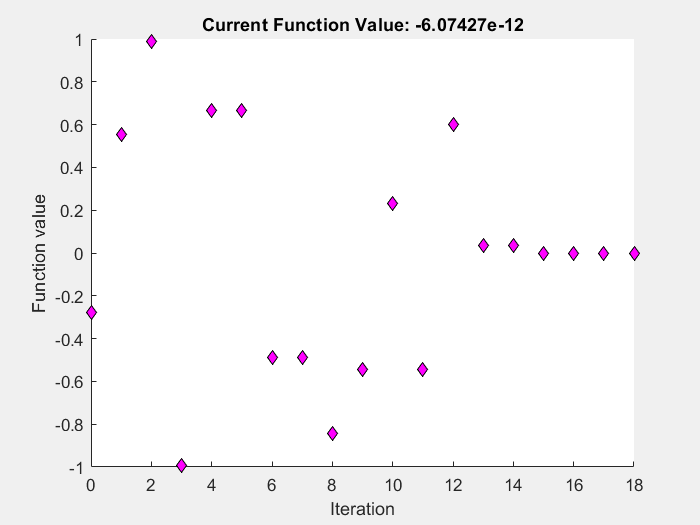

x = 9.9218


option = optimset('PlotFcns',@optimplotfval, 'Display','iter');
x = fzero(fun,x0,option)